clear
clc

% IMPORTING DATA FROM GOOGLE DRIVE, DOWNLOAD AND UNZIP

% Defined file IDs 
file_urls = {
    'normal_1', '1vp6kQ4FgtZ26NnHSCu7ZT_DJzikFK6D1';
    'normal_2', '12tRc-RxkcW-gYf5sfgxSLpFkozalT30f';
    'normal_3', '1IqBkXzdZpMwWTw6jBxia_GIRqeRm_XKn';
    'viral_1', '1zXgvcuv10Zej13F9N2CtNROMR8w1l37t';
    'viral_2', '1ccZIUBOsHVKjDtR70H8gV3ikRGr86E1W';
};

% Downloading and unzipping the images
for i = 1:size(file_urls, 1)
    name = file_urls{i, 1};
    ID = file_urls{i, 2};
    
    % URL download
    downloadURL = ['https://drive.google.com/uc?export=download&id=', ID];
    
    % Saving image Locally
    websave([name, '.zip'], downloadURL);
    
    % Unzip downloaded images
    unzip([name, '.zip'], name);
end
disp('Downloaded and extracted all images successfully.');

Downloaded and extracted all images successfully.


% ASSIGN ALL IMAGES

% Defining the folder paths for each class
normalFolderPaths = {'normal_1/normal_1', 'normal_2/normal_2', 'normal_3/normal_3'};
viralFolderPaths = {'viral_1/viral_1', 'viral_2/viral_2'};

% Utilize cell arrays to store the images for each class
normalImages = {};
viralImages = {};

% Process normal images
for j = 1:numel(normalFolderPaths)
    % listing of all files in the folder
    files = dir(fullfile(normalFolderPaths{j}, '*.jpeg'));
    
    % Iterate over each image file
    for i = 1:numel(files)
        % Read the image using imread
        imagePath = fullfile(normalFolderPaths{j}, files(i).name);
        normalImages{end+1} = imread(imagePath);
    end
end

% Process viral images
for j = 1:numel(viralFolderPaths)
    % listing of all files in the folder
    files = dir(fullfile(viralFolderPaths{j}, '*.jpeg'));
    
    % Iterate over each image file
    for i = 1:numel(files)
        % Read the image using imread
        imagePath = fullfile(viralFolderPaths{j}, files(i).name);
        viralImages{end+1} = imread(imagePath);
    end
end

% SKEWNESS INTENSITY TEST FOR RANDOM IMAGES

% Select a random viral image
randomViralImage = viralImages{randi(numel(viralImages))};

% Select a random normal image
randomNormalImage = normalImages{randi(numel(normalImages))};

% Flatten and calculate skewness, mean, and standard deviation for the viral image
viralVector = randomViralImage(:);
viralMean = mean(viralVector);
viralStdDev = std(double(viralVector));
nViral = numel(viralVector);
viralSkewness = (nViral/((nViral-1)*(nViral-2))) * sum(((double(viralVector) - viralMean) / viralStdDev).^3);

% Flatten and calculate skewness, mean, and standard deviation for the normal image
normalVector = randomNormalImage(:);
normalMean = mean(normalVector);
normalStdDev = std(double(normalVector));
nNormal = numel(normalVector);
normalSkewness = (nNormal/((nNormal-1)*(nNormal-2))) * sum(((double(normalVector) - normalMean) / normalStdDev).^3);

% Display the skewness, mean, and standard deviation values
disp(['Skewness of random viral image: ', num2str(viralSkewness)]);

Skewness of random viral image: -0.69824


disp(['Mean intensity of random viral image: ', num2str(viralMean)]);

Mean intensity of random viral image: 123.2803


disp(['Standard deviation intensity of random viral image: ', num2str(viralStdDev)]);

Standard deviation intensity of random viral image: 69.7493


disp(['Skewness of random normal image: ', num2str(normalSkewness)]);

Skewness of random normal image: -0.14816


disp(['Mean intensity of random normal image: ', num2str(normalMean)]);

Mean intensity of random normal image: 96.0502


disp(['Standard deviation intensity of random normal image: ', num2str(normalStdDev)]);

Standard deviation intensity of random normal image: 64.7148


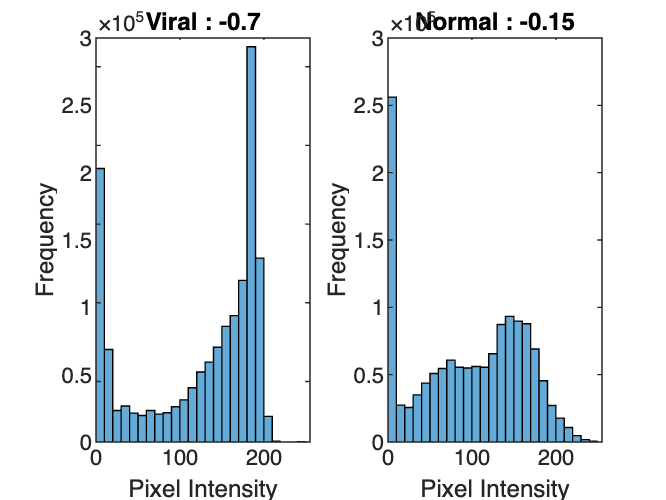


% Plot histograms and display skewness for the random viral image
figure;
subplot(1, 2, 1);
histogram(double(viralVector), 'BinEdges', 0:10:256, 'FaceColor', '#0072BD', 'EdgeColor', 'black');
title(['Viral : ', num2str(round(viralSkewness, 2))]);
xlabel('Pixel Intensity');
ylabel('Frequency');
xlim([0 255]);

% Plot histograms and display skewness for the random normal image
subplot(1, 2, 2);
histogram(double(normalVector), 'BinEdges', 0:10:256, 'FaceColor', '#0072BD', 'EdgeColor', 'black');
title(['Normal : ', num2str(round(normalSkewness, 2))]);
xlabel('Pixel Intensity');
ylabel('Frequency');
xlim([0 255]);

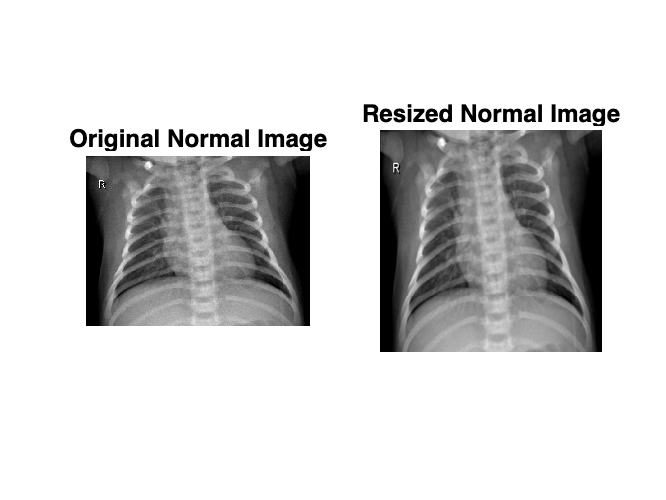

% RESIZE IMAGES TO DESIRED SIZE

% Define the desired size
desiredSize = [224, 224];

% Utilize cell arrays to store the resized images
resizedNormalImages = cell(size(normalImages));
resizedViralImages = cell(size(viralImages));

% Resize images in normalImages
for i = 1:numel(normalImages)
    % Resize the image to the desired size
    resizedNormalImages{i} = imresize(normalImages{i}, desiredSize, 'Method', 'bicubic');
end

% Resize images in viralImages
for i = 1:numel(viralImages)
    % Resize the image to the desired size
    resizedViralImages{i} = imresize(viralImages{i}, desiredSize, 'Method', 'bicubic');
end

% DISPLAY RESIZED IMAGES

% Define the index of images
imageIndex = 1;

% Display original and resized images for the normal class
figure;
subplot(1, 2, 1);
imshow(normalImages{imageIndex});
title('Original Normal Image');

subplot(1, 2, 2);
imshow(resizedNormalImages{imageIndex});
title('Resized Normal Image');

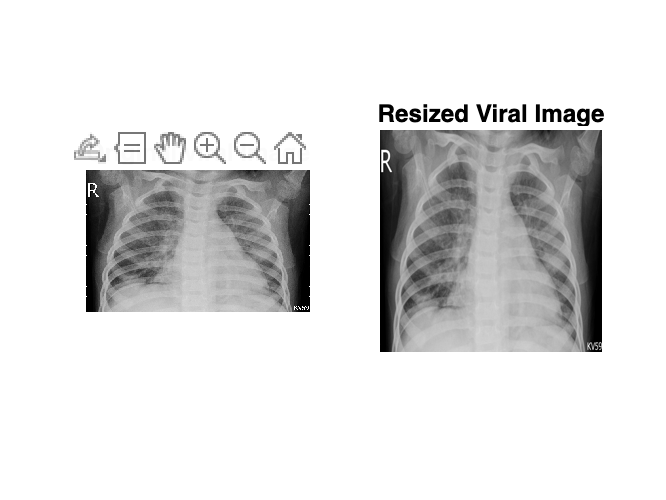


% Display original and resized images for the viral class
figure;
subplot(1, 2, 1);
imshow(viralImages{imageIndex});
title('Original viral Image');

subplot(1, 2, 2);
imshow(resizedViralImages{imageIndex});
title('Resized Viral Image');

% NORMALISATION OF IMAGES

% Define the maximum pixel value
maxPixelValue = 255; 

% Normalize images in normalImages
normalizedNormalImages = cell(size(normalImages));
for i = 1:numel(normalImages)
    % Normalize the image
    normalizedNormalImages{i} = double(normalImages{i}) / maxPixelValue;
end

% Normalize images in viralImages
normalizedViralImages = cell(size(viralImages));
for i = 1:numel(viralImages)
    % Normalize the image
    normalizedViralImages{i} = double(viralImages{i}) / maxPixelValue;
end


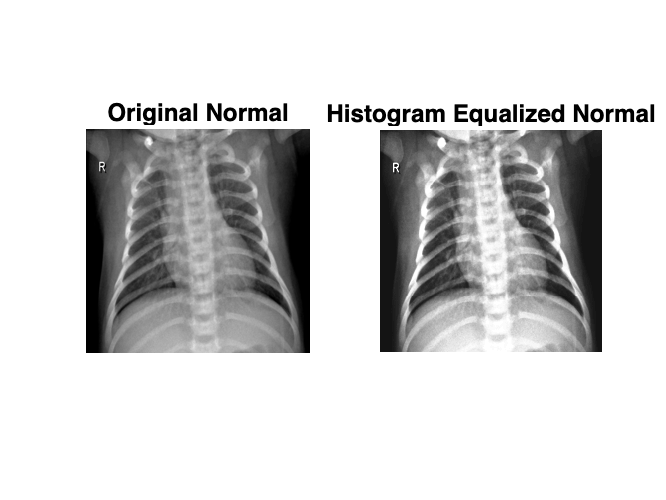

% HISTOGRAM EQUALIZATION OF IMAGES
% Apply histogram equaliZation
equalizedNormalImage = histeq(resizedNormalImages{1});
equalizedViralImage = histeq(resizedViralImages{1});

% DISPLAYING HISTOGRAM EQUALIZED IMAGES

% Display original and histogram-equalized images for normal class
figure;
subplot(1, 2, 1);
imshow(resizedNormalImages{1});
title('Original Normal');

subplot(1, 2, 2);
imshow(equalizedNormalImage);
title('Histogram Equalized Normal');

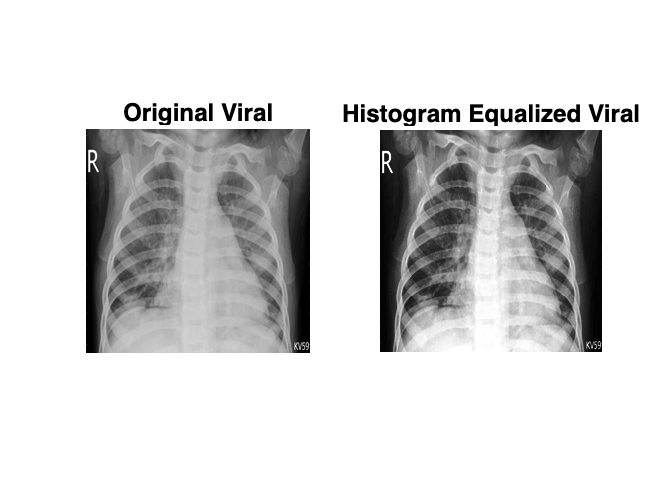


% Display original and histogram-equalized images for viral class
figure;
subplot(1, 2, 1);
imshow(resizedViralImages{1});
title('Original Viral');

subplot(1, 2, 2);
imshow(equalizedViralImage);
title('Histogram Equalized Viral');

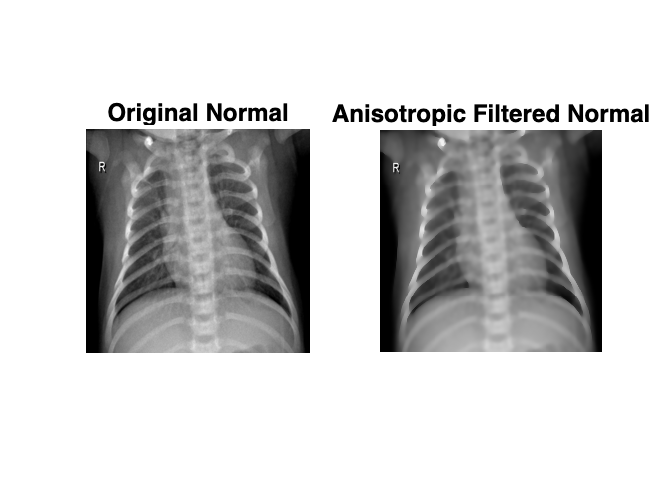

% APPLICATION OF ANISOTROPIC DIFFUSION FILTER

% Anisotropic diffusion filter application
filteredNormalImage = imdiffusefilt(resizedNormalImages{1}, 'NumberOfIterations', 5, 'ConductionMethod', 'exponential');
filteredViralImage = imdiffusefilt(resizedViralImages{1}, 'NumberOfIterations', 5, 'ConductionMethod', 'exponential');

% Display original and anisotropic filtered images for normal class
figure;
subplot(1, 2, 1);
imshow(resizedNormalImages{1});
title('Original Normal');

subplot(1, 2, 2);
imshow(filteredNormalImage);
title('Anisotropic Filtered Normal');

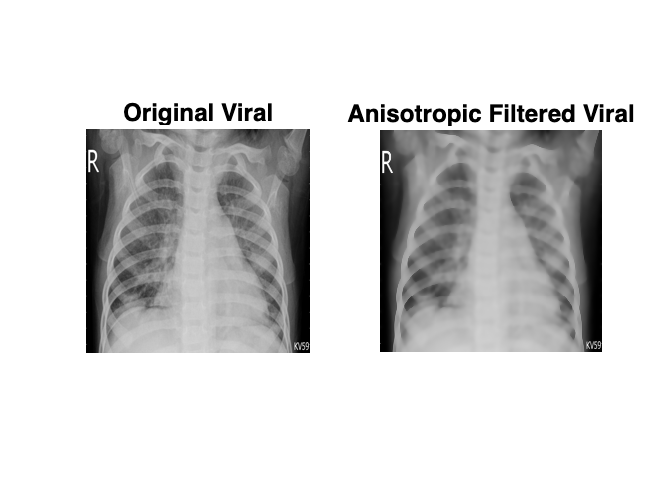


% Display original and anisotropic filtered images for viral class
figure;
subplot(1, 2, 1);
imshow(resizedViralImages{1});
title('Original Viral');

subplot(1, 2, 2);
imshow(filteredViralImage);
title('Anisotropic Filtered Viral');

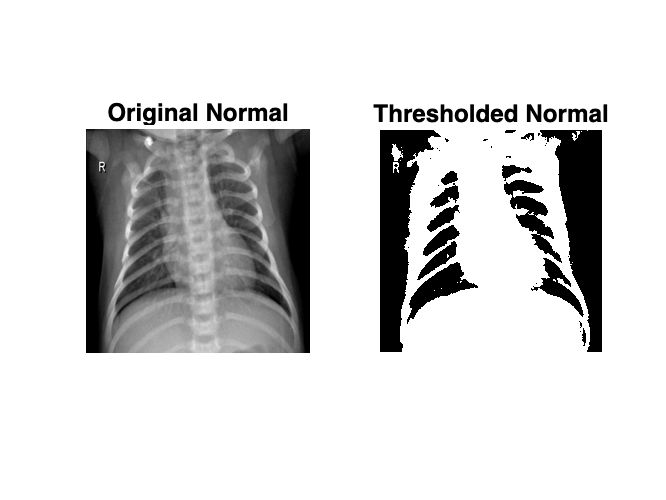

% APPLICATION OF THRESHOLDING USING OTSU'S METHOD

% Apply thresholding (Otsu's method) to both normal and viral images
thresholdedNormalImage = imbinarize(resizedNormalImages{1}, graythresh(resizedNormalImages{1}));
thresholdedViralImage = imbinarize(resizedViralImages{1}, graythresh(resizedViralImages{1}));

% Display original and thresholded images for normal class
figure;
subplot(1, 2, 1);
imshow(resizedNormalImages{1});
title('Original Normal');

subplot(1, 2, 2);
imshow(thresholdedNormalImage);
title('Thresholded Normal');

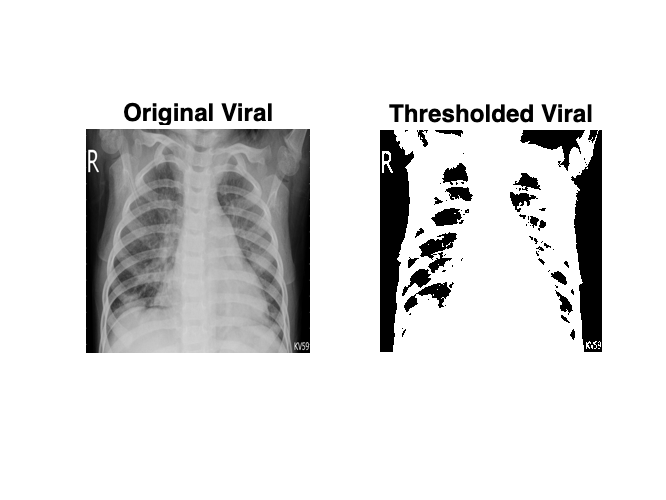


% Display original and thresholded images for viral class
figure;
subplot(1, 2, 1);
imshow(resizedViralImages{1});
title('Original Viral');

subplot(1, 2, 2);
imshow(thresholdedViralImage);
title('Thresholded Viral');

% CONCATENATE AND HOG

% Concatenate the images and labels
allImages = [resizedNormalImages, resizedViralImages];
allLabels = [zeros(1, numel(resizedNormalImages)), ones(1, numel(resizedViralImages))]; % Normal: 0, Viral: 1

% Initialize matrix to store HOG features
cellSize = [8 8]; % HOG cell size
hogFeatureSize = numel(extractHOGFeatures(imresize(im2gray(allImages{1}), desiredSize), 'CellSize', cellSize));
hogFeatures = zeros(numel(allImages), hogFeatureSize);

% Extract HOG features
for i = 1:numel(allImages)
    % Convert to grayscale only if the image is RGB
    if size(allImages{i}, 3) == 3
        grayImage = im2gray(imresize(allImages{i}, desiredSize));
    else
        grayImage = imresize(allImages{i}, desiredSize);
    end
    
    hogFeatures(i, :) = extractHOGFeatures(grayImage, 'CellSize', cellSize);
end

% TRAINING AND TESTING

% Split data into training and testing sets using 80-20 ratio
[trainIdx, testIdx] = holdoutPartition(allLabels, 0.8); % 80% training, 20% testing
trainFeatures = hogFeatures(trainIdx, :);
testFeatures = hogFeatures(testIdx, :);
trainLabels = allLabels(trainIdx)';
testLabels = allLabels(testIdx)';


%SVM CLASSIFIER

% Train an SVM classifier
svmModel = fitcsvm(trainFeatures, trainLabels, 'KernelFunction', 'linear');

% SVM Training accuracy
trainPredictedLabels = predict(svmModel, trainFeatures);
trainAccuracy = sum(trainPredictedLabels == trainLabels) / numel(trainLabels) * 100;
disp(['SVM Training Accuracy: ', num2str(trainAccuracy)]);

SVM Training Accuracy: 100



% Make predictions and evaluate the classifier on test set
predictedLabels = predict(svmModel, testFeatures);
accuracy = sum(predictedLabels == testLabels) / numel(testLabels) * 100;

% Display Testing accuracy
disp(['SVM Testing Accuracy: ', num2str(accuracy)]);

SVM Testing Accuracy: 93.2584



% Confusion matrix
confMatrix = confusionmat(testLabels, predictedLabels);

% Calculate precision, recall, and F1 score
precision = diag(confMatrix) ./ sum(confMatrix, 2);
recall = diag(confMatrix) ./ sum(confMatrix, 1)';
f1Score = 2 * (precision .* recall) ./ (precision + recall);

% Calculate average scores (macro-averaging)
avgPrecision = mean(precision);
avgRecall = mean(recall);
avgF1Score = mean(f1Score);

% Display the calculated metrics
disp(['Precision: ', num2str(avgPrecision)]);

Precision: 0.93232


disp(['Recall: ', num2str(avgRecall)]);

Recall: 0.93364


disp(['F1 Score: ', num2str(avgF1Score)]);

F1 Score: 0.93251


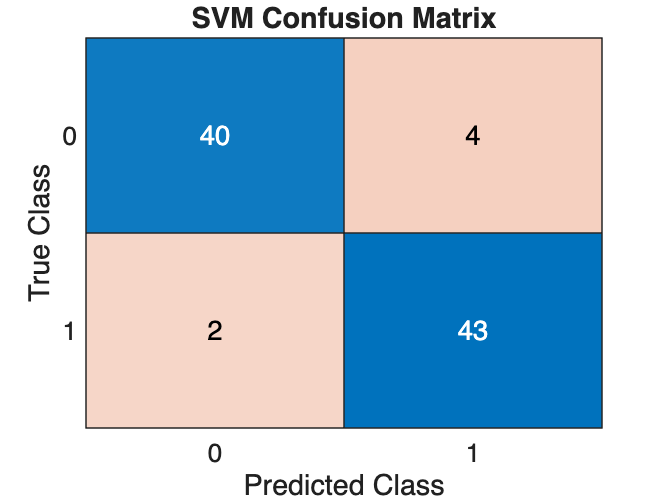


% Display confusion matrix chart
figure;
confusionchart(testLabels, predictedLabels);
title('SVM Confusion Matrix');


% Helper function to create holdout partition
function [trainIdx, testIdx] = holdoutPartition(labels, trainFraction)
    cv = cvpartition(labels, 'HoldOut', 1 - trainFraction);
    trainIdx = training(cv);
    testIdx = test(cv);
end


%% DISPLAYING THE DISTRIBUTION CLASS

% Count the number of samples per class
numNormal = sum(allLabels == 0); % Normal: 0
numViral = sum(allLabels == 1);  % Viral: 1

fprintf('Number of Normal images: %d\n', numNormal);

Number of Normal images: 225


fprintf('Number of Viral images: %d\n', numViral);

Number of Viral images: 225


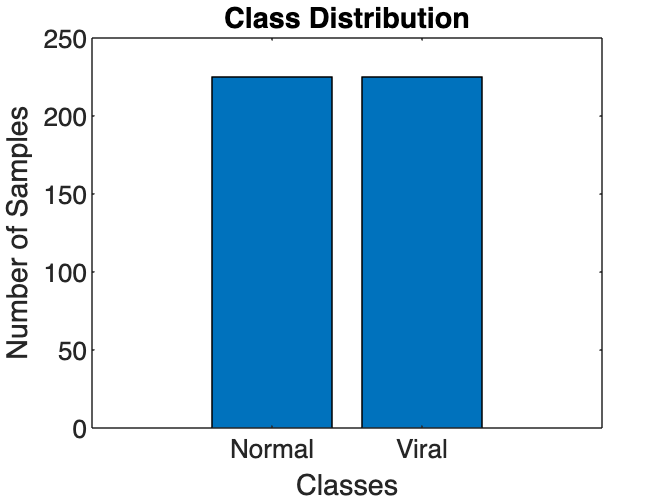


% Visualize the class distribution
figure;
bar([numNormal, numViral]);
set(gca, 'XTickLabel', {'Normal', 'Viral'});
title('Class Distribution');
xlabel('Classes');
ylabel('Number of Samples');